## **Basis:**

simplified model:

front spar + rear spar + skin.

Separate the loading into a force on shear centre(flexural axis) and a torque

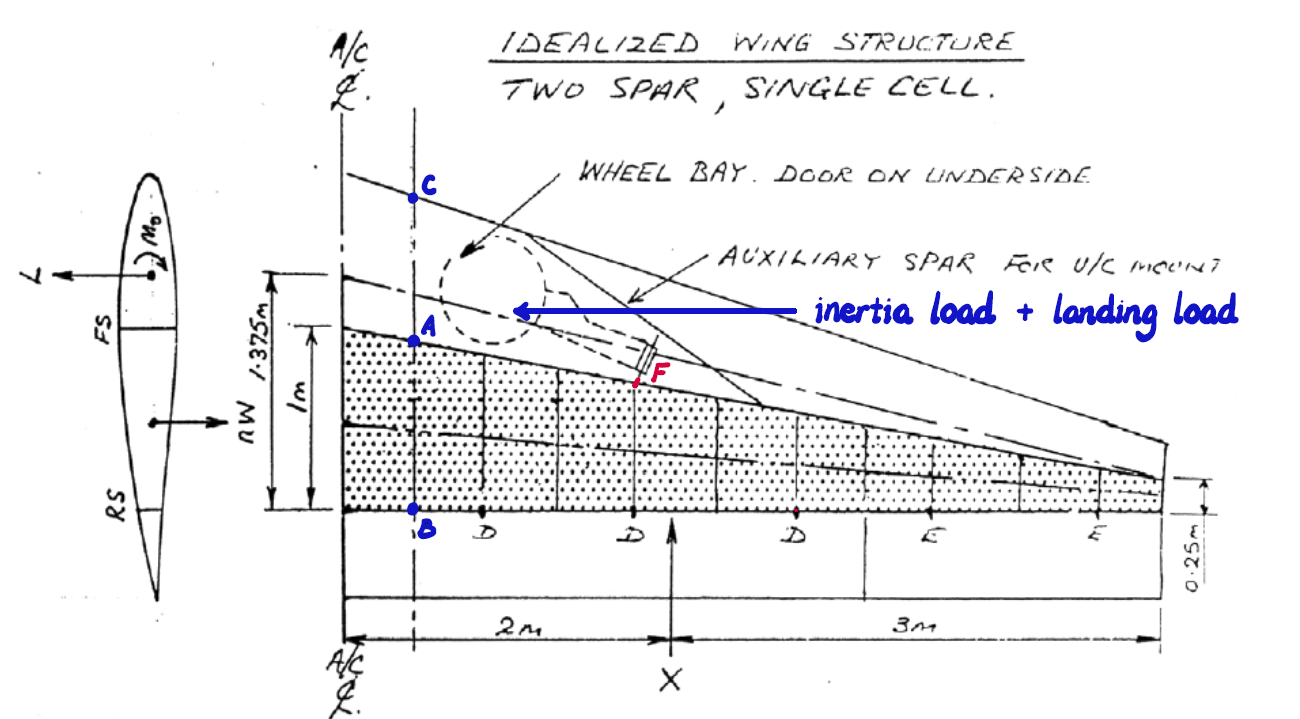

actual model:

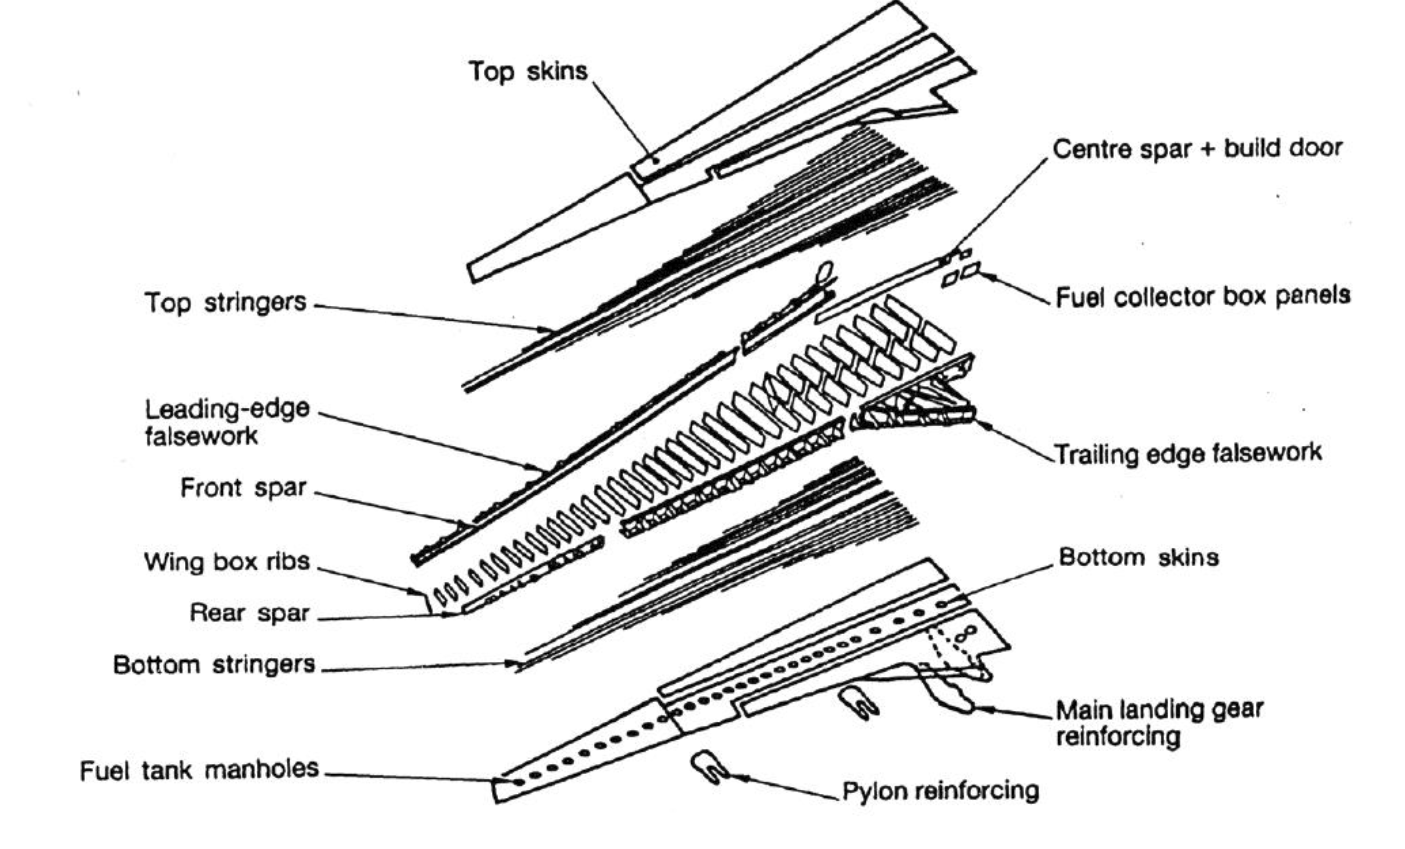

Top surface is under compression, more stringers

Bottom surface is under tension, less stringers

-skin thickness and number of ribs are inversely proportional

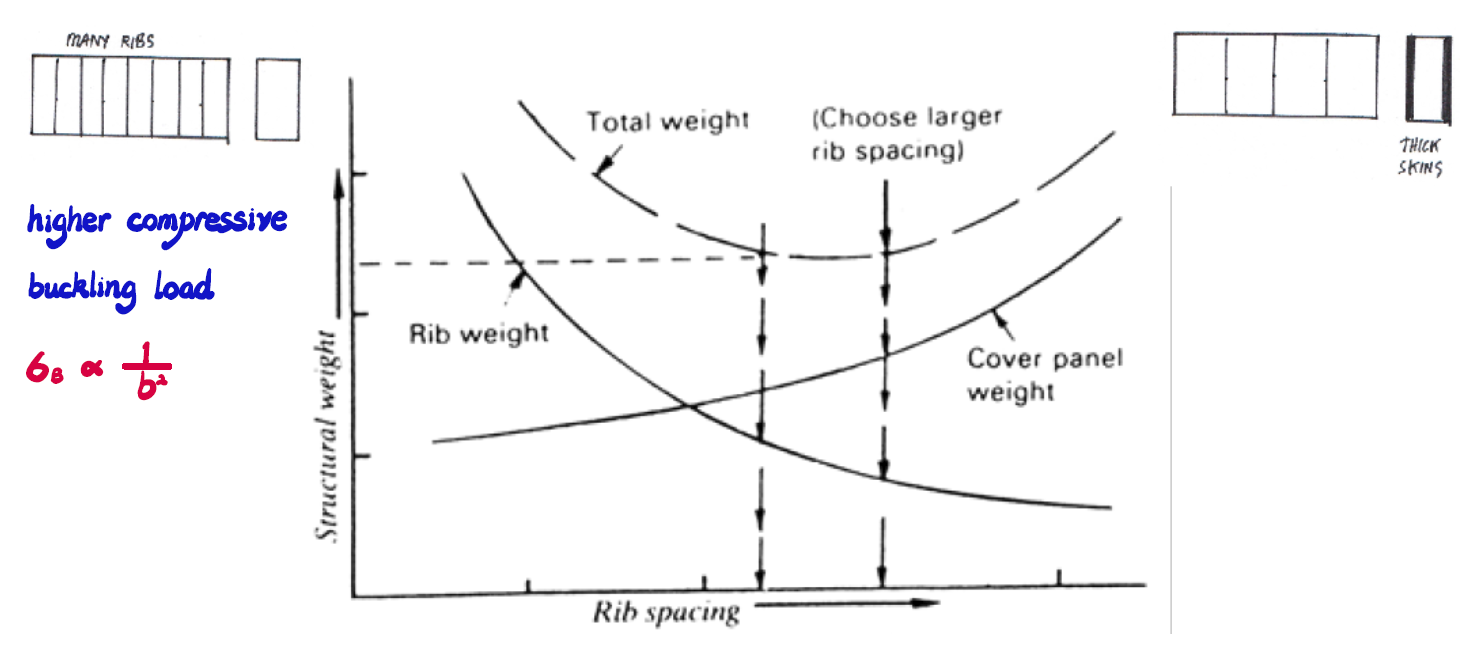

Web:

sine-wave web for composite

metal:

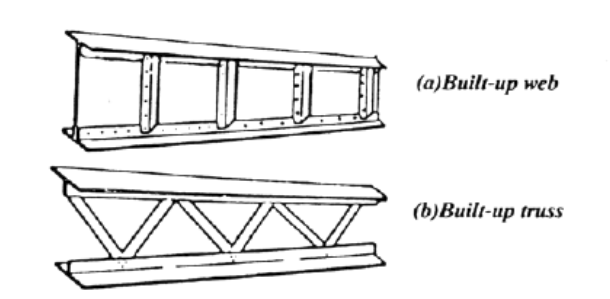

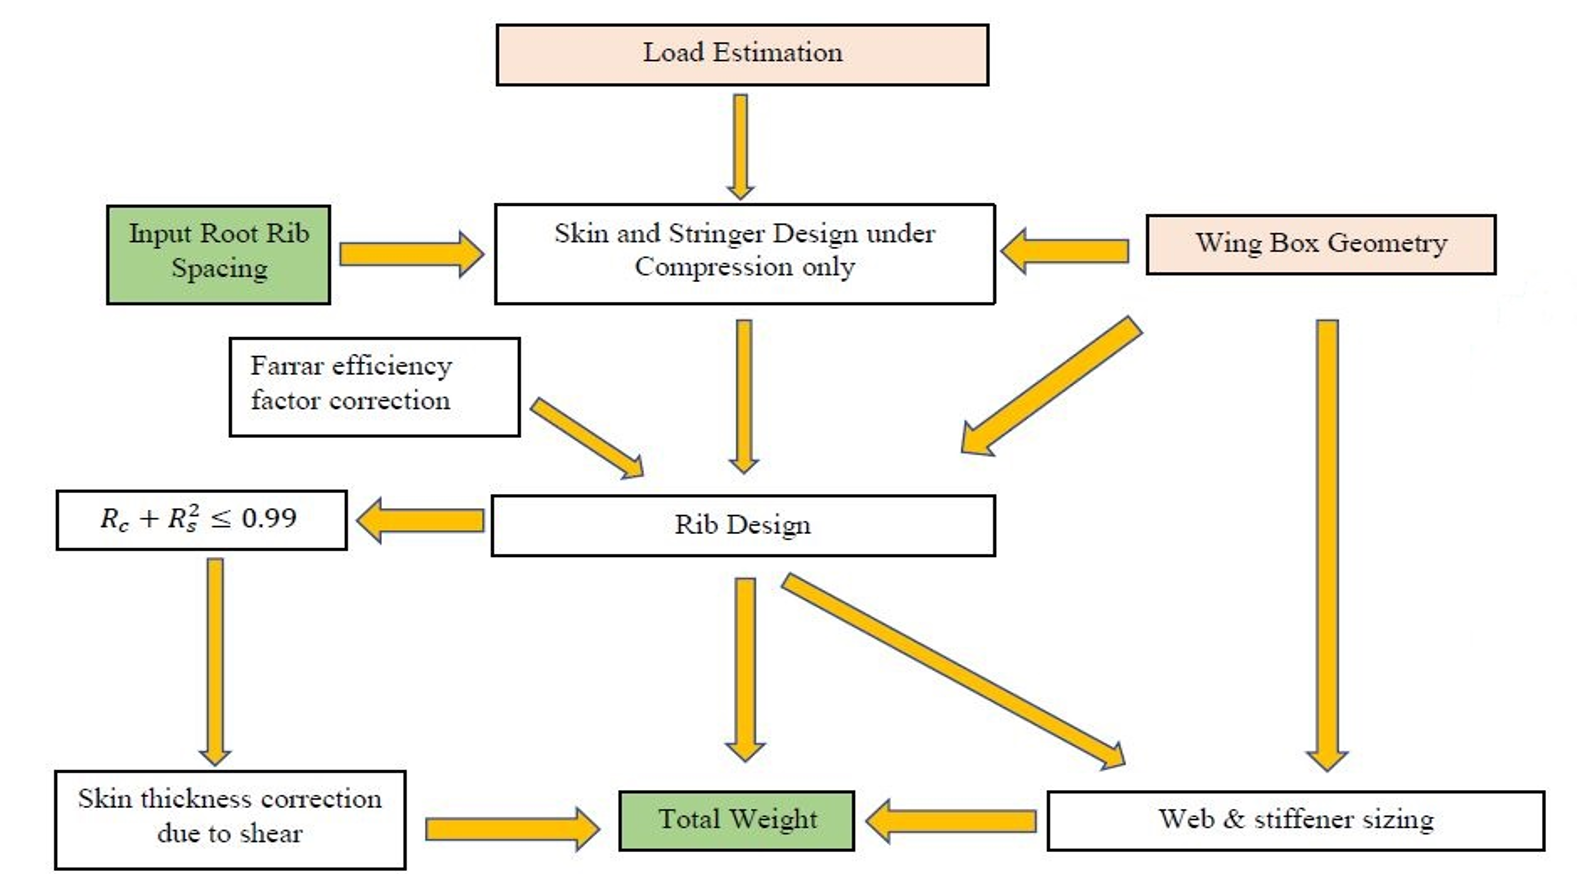

## 1.skin design

sigmacr/sigma0 is from** catchpole diagram**

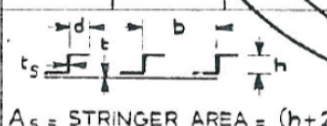

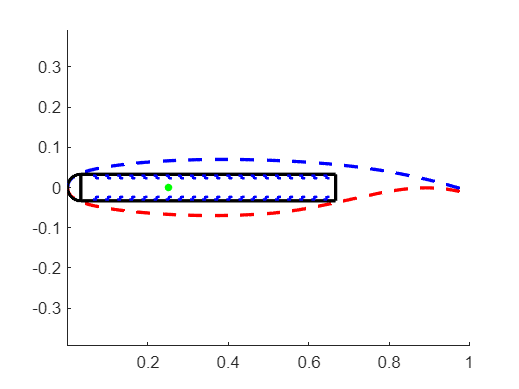

load("airfoil.mat")
load("wing_opt.mat")

wb = wingbox();
%define geometry
wb.c_c = 0.634;
wb.b2_c = 0.066;
wb.R1_c = wb.b2_c/2;
wb.R2_c = wb.R1_c;
%define stringers
wb.N = 20;
wb = wb.calcb1();
wb.ts = 5e-3;
wb.hs = 36e-3;
wb.ds = wb.hs*0.3;
wb = wb.calcStringerArea();
wb.t2 = 7.72e-3;

figure(1)
clf;
wb.drawwithAirfoil(airfoil)


display("ts/t2:")

    "ts/t2:"



display(wb.ts/wb.t2)

    0.6477



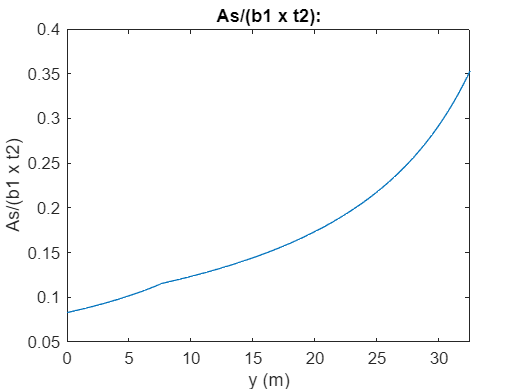


figure(2)
clf;
plot(wing_opt.stripy, wb.As./(wb.b1_c.*wing_opt.cn)./wb.t2)
title("As/(b1 x t2):")
xlabel("y (m)")
ylabel("As/(b1 x t2)")
xlim([0 wing_opt.s])


sigma_cr = findCricStress(wb,M,wing)